# Detrendig: Hodrick–Prescott filtering [HP]

**Nombre: **Valentina Andrade

**Profesor: **Alexandre Janiak                             ** Ayudantes: **Pablo Vega y Bianca Hincapié

clear;
close all;
% Global settings
warning('off'); % warnings about rank 
figure('Renderer', 'painters', 'Position', [10 10 900 600]); % figures size

En series de tiempo, para que el proceso sea covariance-stationary se debe cumplir que:


$$\begin{array}{l}
{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mu }_t =\mu \;;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\forall \;t\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)\\
E\left\lbrack \left(x_t -\mu_t \right)\left(x_{t-\tau } -\mu_{t-\tau \;} \;\right)\right\rbrack =E\left\lbrack \left(x_{t+s} -\mu_{t+s} \right)\left(x_{t-\tau +s} -\mu_{t-\tau \;+s} \;\right)\right\rbrack ;\;\;\;\;\;\;\forall t,s,\tau \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)
\end{array}$$


En términos simples, las ecuaciones indican que una serie de tiempo sea estacionaria, la media (2) y la covarianza (3) no deben cambiar con el tiempo.Típicamente, este no es el caso, siendo común trabajar con series que tienen tendencias y ciclos, dando cuenta de procesos no estacionarios. 

Para dar solución a esta problemática es necesario capturar la tendencia de la serie y separarla de ciclo. La idea general del proceso está dada por

  
$${\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x}_t =\tau {\;}_t +c_t +s_{t\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;} \left(4\right)$$
   

Donde cada una corresponde a 


$$\begin{array}{l}
x_{t\;} =\mathrm{serie}\;\mathrm{de}\;\mathrm{tiempo}\\
\tau {\;}_t =\mathrm{tendencia}\\
c_{t\;} =\mathrm{ciclo}\;\\
s_t =\mathrm{estacionalidad}\;
\end{array}$$
                                                       

Para efectos de estos ejercios $s_t =0$

El objetivo de este ejercicio es utilizar el filtro Hodrick y Prescott para separar la tendencia y el ciclo de la serie del precio del cobre. Para ello utilice las siguientes ecuaciones


$$\begin{array}{l}
y^c =\left(I-A^{-1} \right)y\\
y^s =A^{-1\;} y\\
A=I+\lambda \;K^{\prime } K
\end{array}$$


Donde I es la matriz identidad, $\lambda \;$ el parámetro de sensibilidad de la tendencia a la fluctuaciones a corto plazo y $K$ correspondea la matriz tridiagonal

Responda las siguientes preguntas

#### (a) Importa las series de precio del cobre ($\left.{\mathrm{cu}}_t \right)$, inflación $\pi_t$ y el precio del barril de petróleo Brent ($p_t$) haciendo uso de comandos de Matlab

importdata; % Funcion para importar datos
y = data{:,vartype("numeric")}; % Extraer de tabla elementos numerics

Primero, iniciaré mostrando la serie de datos importados de manera descriptiva

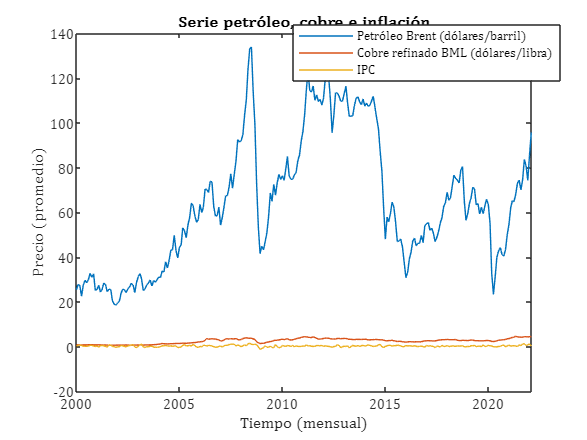

figuredescriptive(data.(1),y) % Grafico descriptivo

#### (b) Cree una que cumpla con las siguientes características:

- Input: (1) serie que desea descomponer y (2) parámetro de sensibilidad $\lambda$

- Output: (1) tendencia y (2) ciclo de la serie

La función que cree se llama **hp_filter. **Dentro de ella aparecen los comentarios del paso a paso de como la construí. Lo interesante es que esta función descompone no solo para 1 serie sino que para varias a la vez (una matriz de series) y da como resultado una mariz de series de tendencias y ciclos. 

lambda = 1600; % Para probar la función
[ytrend, ycycle] = hp_filter(y,lambda) % Funcion HP filter

ytrend =    28.1146    0.8397    0.4197
   28.0566    0.8350    0.4078
   27.9969    0.8303    0.3958
   27.9337    0.8255    0.3836
   27.8646    0.8207    0.3715
   27.7840    0.8158    0.3596
   27.6860    0.8106    0.3481
   27.5658    0.8051    0.3371
   27.4191    0.7992    0.3264
   27.2434    0.7928    0.3159


ycycle =    -2.7146   -0.0033   -0.2197
   -0.2866   -0.0182    0.1922
   -0.6369   -0.0413    0.3042
   -5.3937   -0.0640    0.1164
   -0.4646   -0.0108   -0.1715
    1.8960   -0.0205   -0.1596
    0.8240    0.0056   -0.2481
    2.4742    0.0367   -0.0371
    5.3609    0.0900    0.2736
    3.6866    0.0683    0.2841


#### (c) Grafique la serie original del precio del cobre junto a las tendencias obtenidad para un vector de sensibilidad $\lambda \;\left\lbrack 6\ldotp 25\;\;1600\;\;\;129\ldotp 000\right\rbrack \ldotp$ Interprete brevemete.

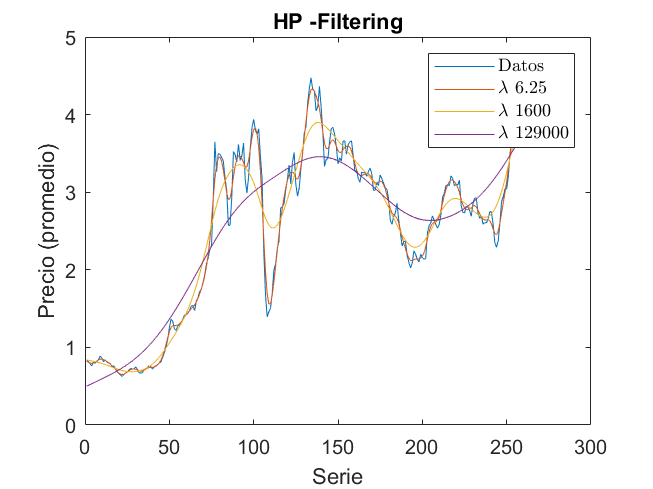

lambda = [6.25 1600 129000];
% Dado que no se recomienda renombrar dinámicamente en matlab se crea cada
% objeto a mano
[ytrend625, ycycle625] = hp_filter(y,lambda(1));
[ytrend16, ycycle16] = hp_filter(y,lambda(2));
[ytrend129, ycycle129] = hp_filter(y,lambda(3));
graph = [y(:,2) ytrend625(:,2) ytrend16(:,2) ytrend129(:,2)]; % Matriz con variables de cobre
hpfigure(graph) % Grafico 

**Interpretación econométrica**

Cuando Hodrick, y Prescott (1997) propusieron un procedimiento para representar las series de tiempo, pensaron en el problema del componente ciclico y tendencial de los fenómenos temporales, sobre todo por las diferencias en análisis que producián no reconocer estos componentes. 

En ese sentido, este método para filtrar estos componentes es bastante útil para análisis macroeconómicos de series de tiempo, como el precio del cobre y la inflación. Como muestra Uhlig (1995, p. 46) el método remueve la tendencia de un set de datos cuando  


$$\min \sum_{t\;\epsilon \;T} \left({\left(s_t -\tau {\;}_t \right)}^2 +{\lambda \left(\left(\tau_{t+1\;} -\tau {\;}_t \;\right)-\left(\tau {\;}_t -\tau {\;}_{t-1} \right)\right)}^2 \right)\;$$


Así, a medida que crece $\lambda \;$las diferencia entre la tendencia y el ciclo se van a ir homogenizando respecto al valor tendencial actual y pasado. 

Justamente esto es lo que se puede evidenciar en la figura construida con** figurehp.m. **Entre menor es el parámetro de sensibilidad, más similar es a la serie original. Mientras que en el caso de la línea púrpura se puede evidenciar un suavizamiento del ciclo mucho más pronunciado. 

**Interpretación económica**

En general, existe una relación estrecha entre el precio del cobre y el ciclo económico en Chile (De Gregorio y Labbe, 2011). Por ejemplo, investigaciones han mostrado que si la política fiscal se conduce bajo la regla de superávit estructural, entonces un aumento del 10% en el precio del cobre incrementaría el PIB en solo 0,05% y generaría una pequeña caída en la inflación (Medina y Soto, 2007). Principalmente se ha argumentado que esto se debe a las apreciaciones cambiaras que acompañan el shock y el ahorro transitorio de los ingresos desde los hogares. Ahora bien, podemos notar que esta sensibilidad ha ido disminuyendo en el tiempo. Otros modelos modelo dinámica de equlibrio general estocástico (DSGE) han mostrado que la volatilidad del producto respecto a la constribución del precio del cobre la disminuido a corto plazo. Tal como pronosticaban Medina y Soto (2007) existe un efecto de amortiguación  de los shocks por parte del tipo de cambio real: si bien la volatilidad ha aumentado a corto plaozo, a largo plazo se ha mantenido estable. 

Para cerrar, este último punto es importante para entender la metodología y la gráfica propuesta. A corto plazo, el precio del cobre está fuertemente relacionado al ciclo macroeconómico, por lo que su componente cíclico puede ser influyente de su distribución no desestacionalizada. Mientras que a largo plazo el efecto del precio del cobre tendería a ser menor, sobre todo considerando en que en los últimos años la regla fiscal en Chile ha estado fija (sobre todo después de la crisis subprime) y el régimen de metas de inflación han jugado un rol clave en la estabilización. 

#### (d) Estime una regresión lineal mediante OLS de los siguientes modelos


$$\begin{array}{l}
\mathrm{M1}:\pi_{t\;} =\beta_0 +\beta {\;}_1 \;\pi {\;}_{t-1} +\beta {\;}_{2\;} \;{\mathrm{cu}}_t +\beta_{3\;} \;{\mathrm{cu}}_{t-1} +\epsilon \\
\mathrm{M2}:\pi_{t\;} =\beta_0 +\beta {\;}_1 \;\pi {\;}_{t-1} +\beta {\;}_{2\;} \;p_t +\beta_{3\;} \;p_{t-1} +\epsilon 
\end{array}$$


Para ello he creado una función que tiene de input los datos y de output los dos modelos de regresión solicitados. Esto se ha hecho de manera alegebraica. 

[m1,m2] =regresions(data) % Funcion para hacer regresiones 

m1 =     0.0443    0.3917   -0.0730    0.1234


m2 =     0.0484    0.4159    0.0109   -0.0091


Para hacer más fácil la interpretación se han realizado dos gráficos

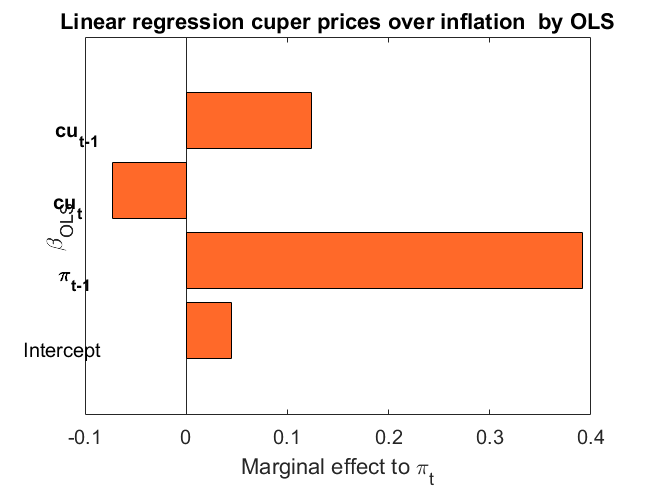

m1regression(m1)

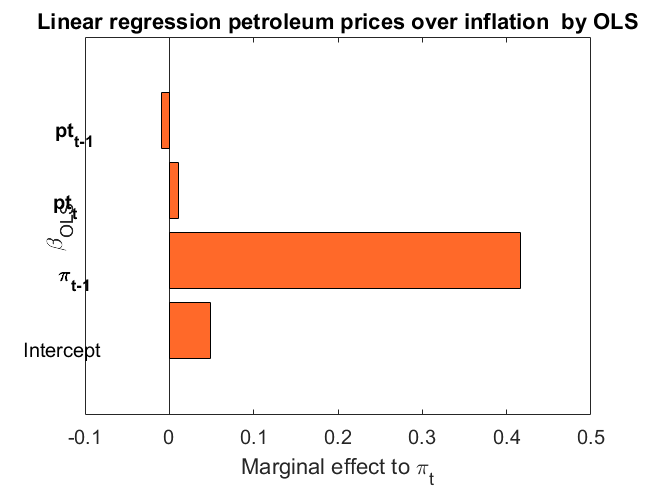

m2regression(m2)

Como se había descrito más arriba, si bien se ha relevado la importancia del precio del cobre para la performance macroeconómica, recientes investigaciones han mostrado que su importancia sobre la contribución al PIB y la inflación ha ido disminuyendo. Según De Gregorio y Labbe (2011) las razones son dos:

 1. La regla fiscal ha sido muy importante en la gestión macroeconómica. Esta ha otorgado una capacidad predictiva sobre la política fiscal, y con ello, la política monetaria ha podido ajustarse mucho mejor ante contextos inflacionarios. 

2. La política monetaria basada en metas ha sido clave para entender las tendencias de inflación en Chile. Es decir, en la medida en que el Banco Central ha fijado las expectativas respecto a la inflación esperada, y su alta capacidad de acción ante las reglas fiscales claras, la mejor forma de predecir la inflación futura se ha transformado en ver el comportamiento del Banco Central y sus anuncios de tasas de política monetaria. 

De este modo, a diferencia de investigaciones anteriores como las de Calvo y Mendoza (1999), el *path de la inflación *está fuertemente influenciado por la inflación misma más que en el precio del cobre o el precio del cobre dividido en el petróleo. De hecho, tal como argumenta De Gregorio y Labbé (2011) las ideas de Calvo (1999) y Caballero (2002) podrían haber sido relevantes incluso cuando Chile estaba limitado en el acceso de financiamiento internacional. A su vez, estos estudios tampoco consideran los datos más recientes de los 2000s donde los resultados de las fluctuaciones incluso han sido más moderadas. 

En síntesis, tanto el cobre como el petróleo han perdido en la última década su poder predictivo sobre la inflación, y más bien la inflación pasada es la que por ahora nos otorga sus mejores predicciones. No obstante esta estabilidad hoy podría ser puesta en duda: la crisis económica y financiera producida por la pandemia, la presión por stock de petróleo ante el bloqueo a Rusia por la guerra en Ucrania podrían ser más que un *shock *transitorio y cambiar el rumbo de la economía. 

### Referencias

[Banco Central (2022) Series de precios de cobre y petróleo.](https://si3.bcentral.cl/Siete/ES/Siete/Cuadro/CAP_EI/MN_EI11/EI_PROD_BAS/637185066927145616)

[Uribe, M and Schmitt, S (2017) Open Economy Macroeconomics. Princeton University Press](http://www.columbia.edu/~mu2166/book/empirics/slides_empirics.pdf)

Hodrick, R.J. and E.C.Prescott (1997), "Postwar U.S. Business Cycles: An Empirical Investigation." Jounal of Money, Credit and Banking. 29(1), Feb. pp. 1--16.

Medina, J. P., & Soto, C. (2007). *Copper price, fiscal policy and business cycle in Chile* (p. 1). Santiago: Banco Central de Chile. [https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.506.2292&rep=rep1&type=pdf](https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.506.2292&rep=rep1&type=pdf)

[De Gregorio, J., & Labbé, F. (2011). *Copper, the real exchange rate and macroeconimic fluctuations in Chile*. Santiago: Central Bank of Chile](https://d1wqtxts1xzle7.cloudfront.net/40081899/Copper_the_Real_Exchange_Rate_and_Macroe20151116-27267-1ybftqf-with-cover-page-v2.pdf?Expires=1648419559&Signature=RZ9f8yFm4mLVLn-GMKvA7G2-seq3e1~tiRU9a8jjZ0Ob-wfqKjEw38oFFaSbJ7xA2NgplyzUVz2WpXmnyjeGhaXoF~95K8861TfPwepPJ2oKpvsWJFVVIYvBpw8Md9IXXAZMvLp5SqB-geHJ~MZLZpK3TUPowFO514DF4TF9yF8sEzbs3v9Bdke1xeWvvOLBzTbiUiDco5~ks2CmA4DVlPo7mF9Xphxyh-zst2fL~FS-7sR5OWDgXJeEh1pY6CzRu-EJr8vv46znlv13n9rKAPo3A2MIug-GKDXDvIoP58kdD6RxoasLujXaiRtN6jFiNKYIKNrslTbbdcif~90QRw__&Key-Pair-Id=APKAJLOHF5GGSLRBV4ZA)

[Uhlig, H (1995) A toolkit for Analizing Nonlinear Dynamic Stochastic Models. CentER, University of Tilburg](https://www.sfu.ca/~kkasa/uhlig1.pdf)

[Mathworks (2022) Tutorial why variables shold not be named dynamically.](https://la.mathworks.com/matlabcentral/answers/304528-tutorial-why-variables-should-not-be-named-dynamically-eval)